# **drawAngDim**

# **drawAngDim3p**

Draw angle dimension

## Description

Angle dimension  measures the angle between two directions.

## Syntax

drawAngDim( form, ad1, ad2, xc, yc, sang, ang, td, tang)

drawAngDim3p( form, ad1, ad2, xc, yc, x1, y1, x2, y2, rt, at )

drawAngDim(__,'-str',str)

drawAngDim(_,LineSpec)

### Description

### Method

drawAngDim uses drawArcArrow to draw an angle dimension . For drawing text, the function drawAngDim use current text attributes. They can be changed by function drawSet.

## Arguments

### Input Arguments

**form **- arrowhead form: use 1,2,3,11 for arrow

**d1,d2 **- arrowhead width and height

**xc,yc **- the center point

for drawAngDim

**sang **- start angle in degrees

**ang **- central angle in degrees

or for drawAngDim3p

**x1, y1**,  -- the first point

 **x2, y2**   -- second point

**rt,at    **- polar coordinates of text location. 

### Optional Name-Value Pair Input Arguments

**'-str'|'-txt',str** - dimension text

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

## Examples

### Example 1

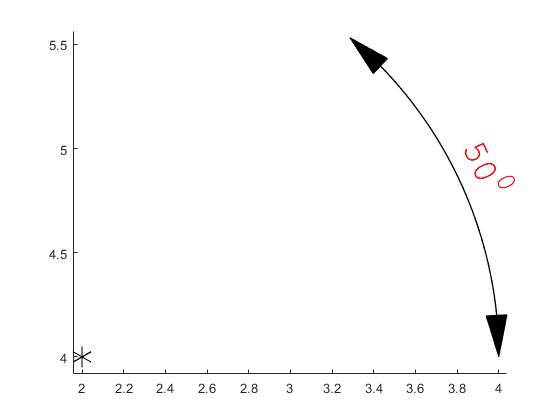

drawInit
ad1 = 0.2; ad2 = ad1/2;
x1 = 2; y1 = 4;
r = 2; sang = 0; ang=50; at = ang/2;
gkSet('FontSize',26)
drawPoint(1,ad1/2,x1,y1)
drawAngDim(3,ad1,ad2,x1,y1,sang,ang,r,at)

%grid on

### Example 2

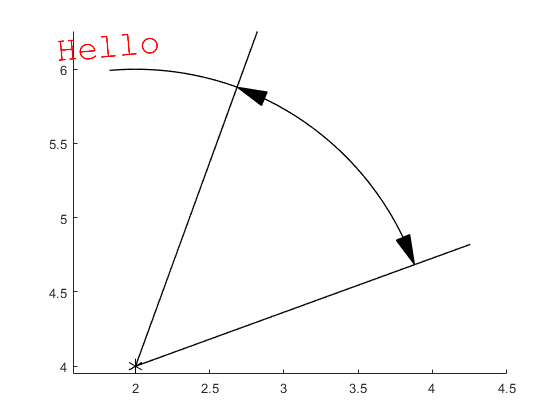

drawInit
ad1 = 0.2; ad2 = ad1/2;
x1 = 2; y1 = 4;
r = 2; sang = 20; ang=50; at = 1.5*ang;
gkSet('FontSize',26)
drawPoint(1,ad1/2,x1,y1)
drawAngDim(3,ad1,ad2,x1,y1,sang,ang,r,at,'-str','Hello')
drawLine(x1,y1,'-rtheta',1.2*r,sang)
drawLine(x1,y1,'-rtheta',1.2*r,sang+ang)

### Example 3

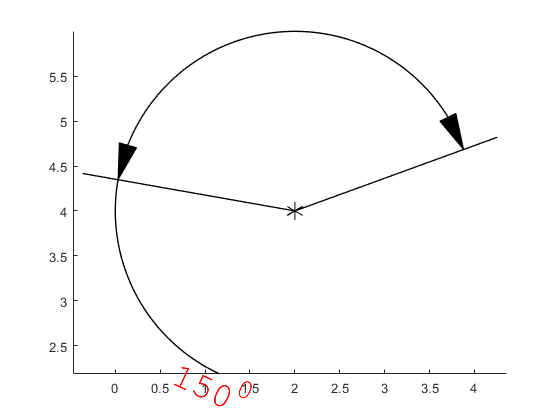

drawInit
ad1 = 0.4; ad2 = ad1/2;
x1 = 2; y1 = 4;
r = 2; sang = 20; ang=150; at = 1.5*ang;
gkSet('FontSize',26)
drawPoint(1,ad1/2,x1,y1)
drawAngDim(3,ad1,ad2,x1,y1,sang,ang,r,at)
drawLine(x1,y1,'-rtheta',1.2*r,sang)
drawLine(x1,y1,'-rtheta',1.2*r,sang+ang)

### Example 4

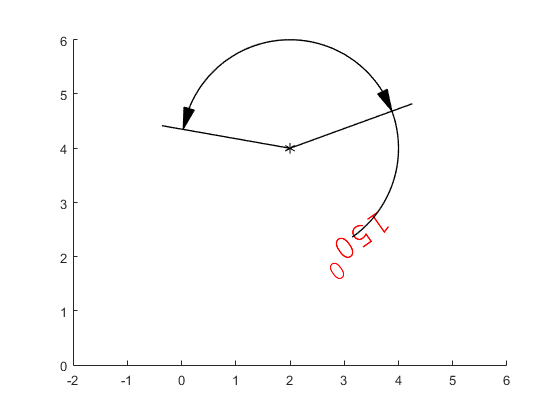

drawInit
drawLimits(-2,6,0,6)
ad1 = 0.4; ad2 = ad1/2;
x1 = 2; y1 = 4;
r = 2; sang = 20; ang=150; at = -0.5*ang;
gkSet('FontSize',26)
drawPoint(1,ad1/2,x1,y1)
drawAngDim(3,ad1,ad2,x1,y1,sang,ang,r,at)
drawLine(x1,y1,'-rtheta',1.2*r,sang)
drawLine(x1,y1,'-rtheta',1.2*r,sang+ang)

### Example 5

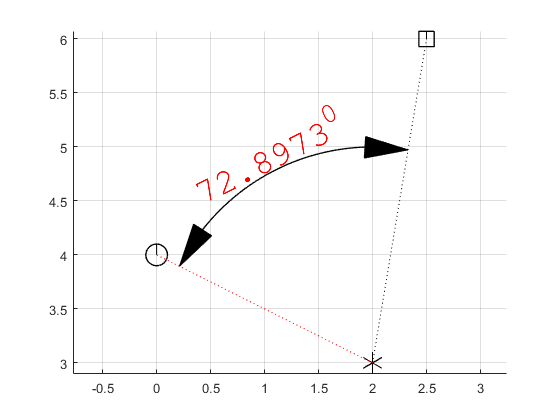

drawInit
ad1 = 0.4; ad2 = ad1/2;
x1 = 2; y1 = 3;
x2 = 2.5; y2 = 6;
xt = 0; yt = 4;
drawSet('FontSize',26,'textColor','r')
drawPoint(1,ad1/2,x1,y1)
drawPoint(2,ad1/2,x2,y2)
drawPoint(3,ad1/2,xt,yt)
drawLine(x1,y1,x2,y2,'k:')
drawLine(x1,y1,xt,yt,'r:')
drawAngDim3p(3,ad1,ad2,x1,y1,x2,y2,xt,yt,2,36); %,'-str','Hello')
grid on

### Example 6

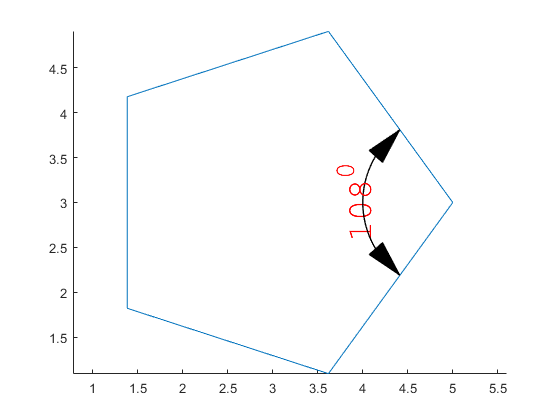

drawInit
p = drawNgon(5,2,3,3);
%drawSet('FontSize',26,'textColor','r')
%drawPoint(1,ad1/2,x1,y1)
%drawPoint(2,ad1/2,x2,y2)
%drawPoint(3,ad1/2,xt,yt)
drawAngDim3p(3,ad1,ad2,p.x(1),p.y(1),p.x(5),p.y(5),p.x(2),p.y(2),1,-54); %,'-str','Hello')

%grid on

## See also

## References